im = cdata;

%reshape
im3column = reshape(im,[],3)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


%select only retina
[~,inx] = ROI(im)

inx =       196365
      196371
      196372
      196373
      196374
      196375
      196376
      196377
      196378
      196379


roi = im3column(inx,:)

roi = 1197940×3 uint8 matrix
   14    0    0
   15    2    0
   17    2    0
   19    1    0
   18    3    0
   17    3    0
   15    4    0
   13    2    0
   13    2    0
   13    2    0


roi = 1197940×3 uint8 matrix
   14    0    0
   15    2    0
   17    2    0
   19    1    0
   18    3    0
   17    3    0
   15    4    0
   13    2    0
   13    2    0
   13    2    0


%select only non vain nor macula
meanG = mean(double(roi(:,2)))

meanG = 35.4385

stdG = std(double(roi(:,2)))

stdG = 18.5202

meanSubStd = meanG - stdG

meanSubStd = 16.9183

meanAddStd = meanG + stdG

meanAddStd = 53.9586


roi2Inx = find((roi(:,2) >= meanSubStd & roi(:,2) <= meanAddStd));

X = roi(roi2Inx,:)

X = 991724×3 uint8 matrix
   44   17   10
   41   17    7
   45   18    9
   46   18    7
   45   18    7
   44   21    7
   43   21    7
   40   17    3
   41   17    7
   42   18    8


%Normalize X in range [0,1]
Xnorm = double(X)/255

Xnorm =     0.1725    0.0667    0.0392
    0.1608    0.0667    0.0275
    0.1765    0.0706    0.0353
    0.1804    0.0706    0.0275
    0.1765    0.0706    0.0275
    0.1725    0.0824    0.0275
    0.1686    0.0824    0.0275
    0.1569    0.0667    0.0118
    0.1608    0.0667    0.0275
    0.1647    0.0706    0.0314


%get SIGMA
SIGMA = sqrt(cov(Xnorm))

SIGMA =     0.0935    0.0525    0.0226
    0.0525    0.0344    0.0167
    0.0226    0.0167    0.0112


SIGMA_target = SIGMA

SIGMA_target =     0.0935    0.0525    0.0226
    0.0525    0.0344    0.0167
    0.0226    0.0167    0.0112


%get V and S from svd function
covs = cov(Xnorm)

covs =     0.0088    0.0028    0.0005
    0.0028    0.0012    0.0003
    0.0005    0.0003    0.0001


[V,S] = svd(covs)

V =    -0.9491    0.3065    0.0729
   -0.3093   -0.8628   -0.3999
   -0.0597   -0.4021    0.9137


S =     0.0097         0         0
         0    0.0003         0
         0         0    0.0000


T = 	1.0e+-3 *

    0.6615    0.3547    0.1449
   -0.1865   -0.0974   -0.0384
   -0.0391   -0.0198   -0.0073


%Normalize roi in range [0,1]
roiNorm = double(roi)/255

roiNorm =     0.0549         0         0
    0.0588    0.0078         0
    0.0667    0.0078         0
    0.0745    0.0039         0
    0.0706    0.0118         0
    0.0667    0.0118         0
    0.0588    0.0157         0
    0.0510    0.0078         0
    0.0510    0.0078         0
    0.0510    0.0078         0


%find mean of the roiNorm data
m = mean(roiNorm)

m =     0.3704    0.1390    0.0316


m_target = double([192 96 32])/255

m_target =     0.7529    0.3765    0.1255


%form T
sc = (S * diag([1 1 0])).^(-1/2)

sc =    10.1642       Inf       Inf
       Inf   54.4134       Inf
       Inf       Inf       Inf


sc(isinf(sc)) = 0

sc =    10.1642         0         0
         0   54.4134         0
         0         0         0


Q = std(Xnorm)

Q =     0.0935    0.0344    0.0112


Q(2) = Q(1)

Q =     0.0935    0.0935    0.0112


Q = diag(Q)

Q =     0.0935         0         0
         0    0.0935         0
         0         0    0.0112


T = V * sc * V' * Q

T =     1.3346   -1.0668   -0.0688
   -1.0668    3.8800    0.2139
   -0.5734    1.7834    0.0991


%form all together to get out put
b = (roiNorm - m) * T + m_target 

b =     0.3306    0.1217    0.0066
    0.3450    0.1317    0.0119
    0.3497    0.1337    0.0124
    0.3484    0.1312    0.0103
    0.3581    0.1392    0.0152
    0.3557    0.1382    0.0149
    0.3571    0.1407    0.0170
    0.3403    0.1298    0.0114
    0.3403    0.1298    0.0114
    0.3403    0.1298    0.0114


%set range back to 0 -255
rgb = b * 255

rgb =    84.3017   31.0440    1.6736
   87.9778   33.5938    3.0365
   89.1739   34.1003    3.1616
   88.8310   33.4585    2.6364
   91.3110   35.5018    3.8743
   90.7129   35.2486    3.8117
   91.0559   35.8904    4.3369
   86.7817   33.0873    2.9115
   86.7817   33.0873    2.9115
   86.7817   33.0873    2.9115


%substitute rgb back to im3column
im3column(inx,:) = uint8(rgb)

im3column = 1950464×3 uint8 matrix
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0


%reshape im3column to displayable image
dis = reshape(im3column,size(im))

dis = 1216×1604×3 uint8 array
dis(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

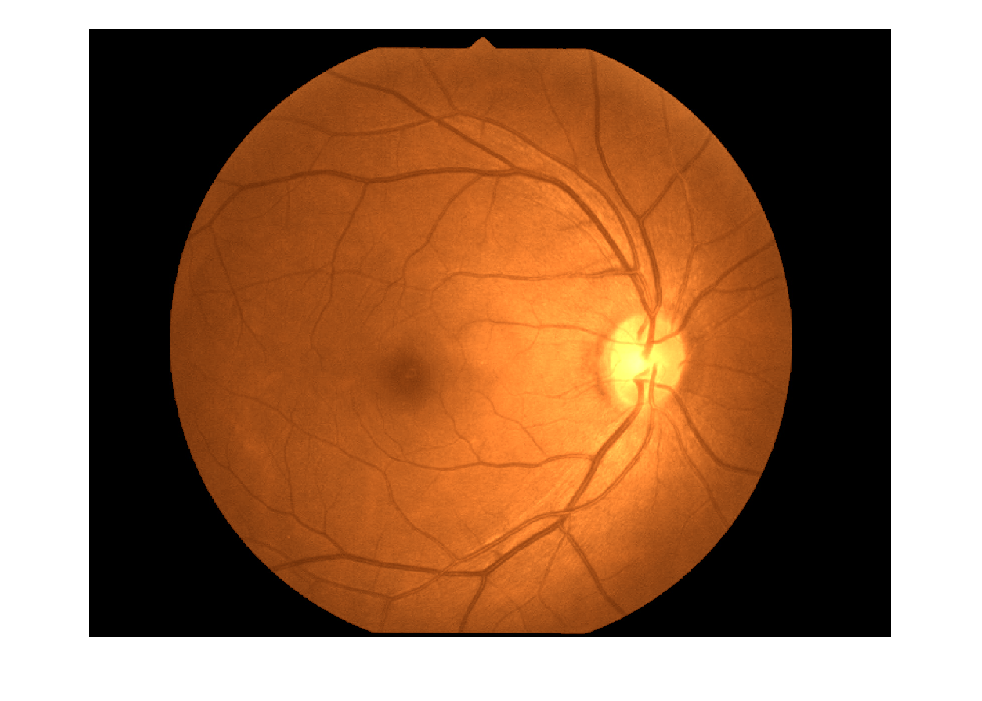

%display
imshow(dis)